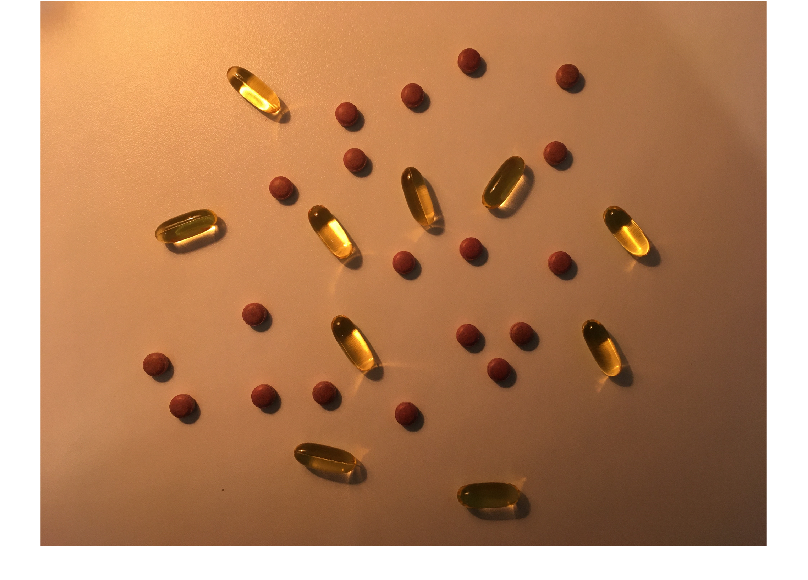

I = imread("mixed_easy.jpg");
imshow(I);

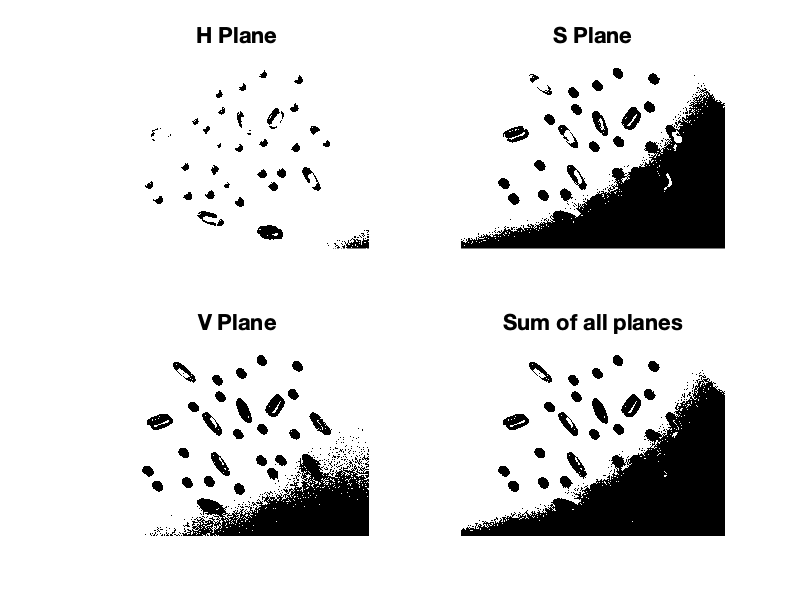

%imtool(I);
%I2 = imcrop(I,[0 0 3432 3004]);
%%Solution: Thresholding the image
%Im=double(img/255)
Im=I;

%% RGB Colour space
hmat=Im(:,:,1);
smat=Im(:,:,2);
vmat=Im(:,:,3);

%%
levelh = 0.335;
levels = 0.4;
levelv = 0.2;
i1=imbinarize(hmat, levelh);
i2=imbinarize(smat, levels);
i3=imbinarize(vmat, levelv);
Isum = (i1&i2&i3);

figure;
subplot(2,2,1), imshow(i1);
title('H Plane')
subplot(2,2,2), imshow(i2);
title('S Plane')
subplot(2,2,3), imshow(i3);
title('V Plane')
subplot(2,2,4), imshow(Isum);
title('Sum of all planes')

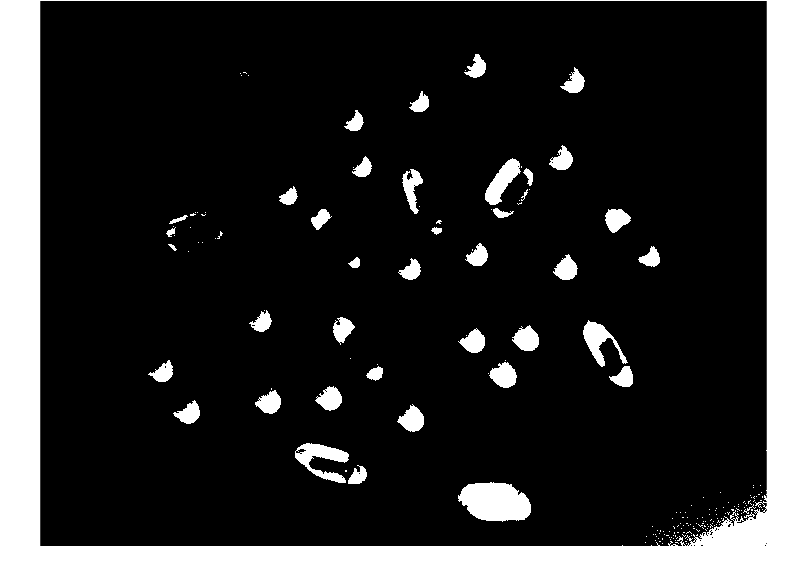


 %% Complement Image and Fill in holes
 Icomp = imcomplement(i1);
 Ifilled = imfill (Icomp,'holes');
 figure, imshow(Ifilled);

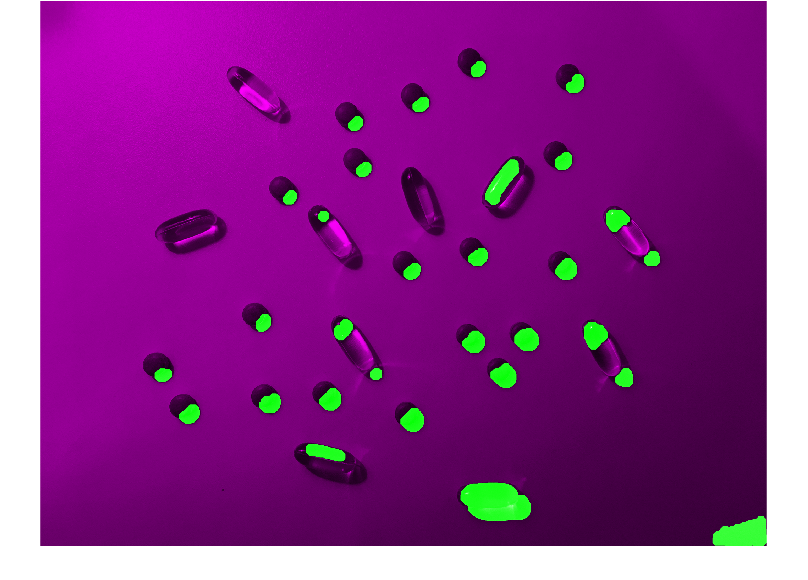


 %%
 se = strel('disk', 30);
 Iopenned = imopen(Ifilled,se);
 figure,imshowpair (Iopenned, I);

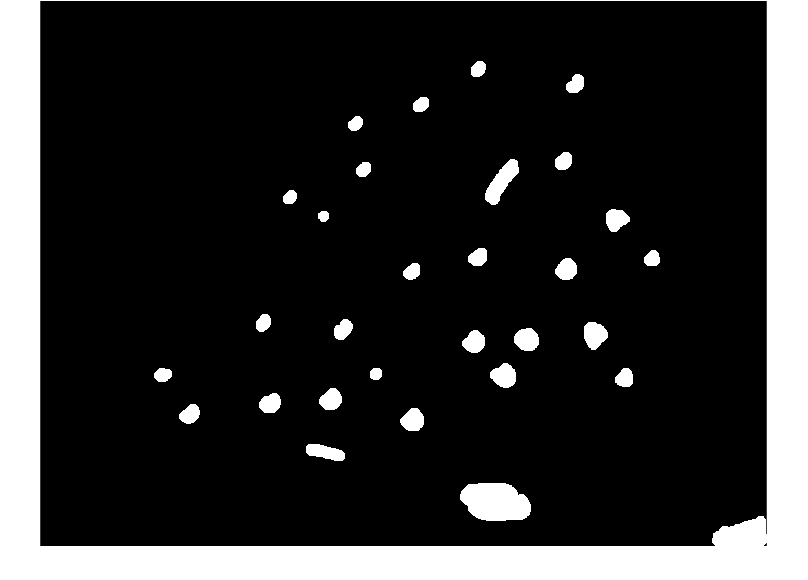

 imshow(Iopenned);

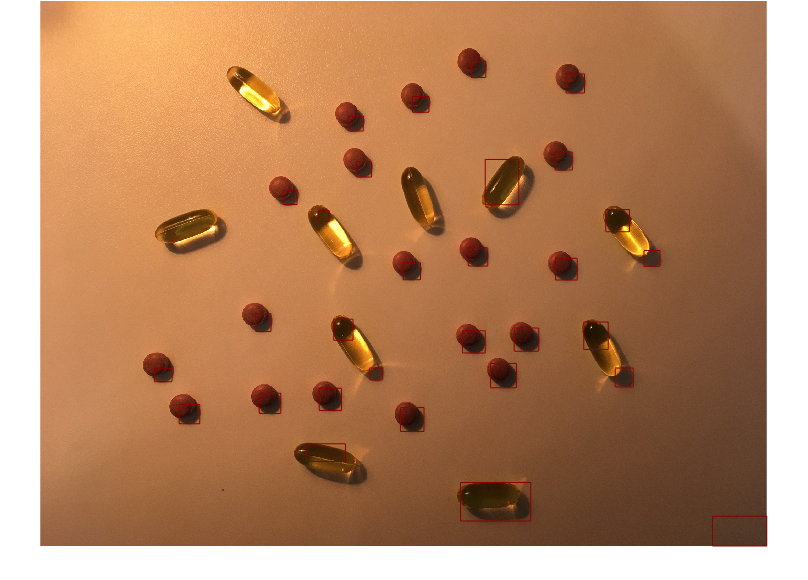


 %% Extract features

 Iregion = regionprops(Iopenned,'centroid');
 [labeled,numObjects] = bwlabel(Iopenned,4);
 stats = regionprops(labeled,'Eccentricity','Area','BoundingBox');
 areas = [stats.Area];
 eccentricities = [stats.Eccentricity];

 %% Use feature analysis to count pill objects
 idxOfMixedPills = find(eccentricities);
 statsDefects = stats(idxOfMixedPills);

 figure, imshow(I);
 hold on;
 for idx = 1 : length(idxOfMixedPills)
     h = rectangle('Position', statsDefects(idx).BoundingBox);
     set(h,'EdgeColor',[.55 0 0]);
     hold on;
 end
 if idx > 10
 title(['There are ', num2str(numObjects), ' objects in the image!'])
 end
 hold off;

imshow(I)
title(strcat(numel(idxOfPills)+ "Pills"))


 %% Convert to grayscale image
 %Igray = rgb2gray(I);
 %imshow(Igray);

 %% Problem illumination doesn't allow for easy segmentation
 %level = 0.4;
 %Ithresh = im2bw(Igray,level);
 %imshowpair (I, Ithresh, 'montage');



